# Brain Scan Demo

*Koby Taswell and Ayush Garg*

This demo tests Optimal Hard Thresholding applied to each slice along Z axis.

filename = 'ABIDE_MRI_data.nii';

Vol = niftiread(filename);

[Nvol, Dvol, snrN, snrD, r] = TestVolume(Vol);
[NvolSq, DvolSq, snrNSq, snrDSq] = TestVolumeSq(Vol);


**For Arbitrary thresholding**

Original Signal to Noise Ratio at each Slice along Z axis

plot(snrN)

Denoised Signal to Noise Ratio at each slice along Z axis

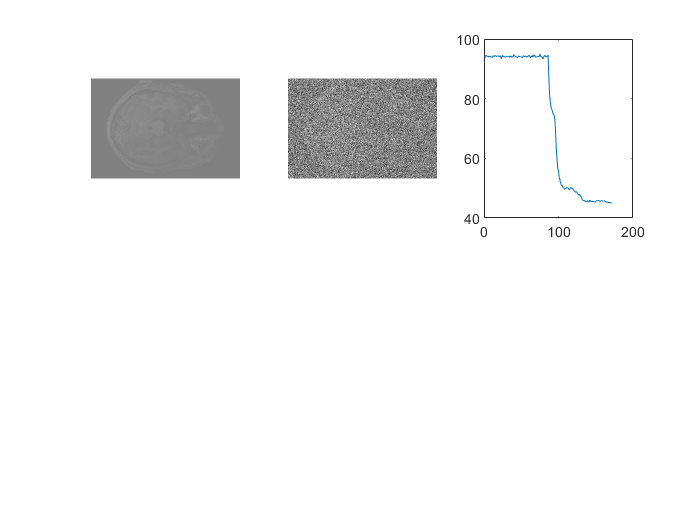

plot(snrD)

Amount of Signal to Noise Reduced by Arbitrary Optimal Hard Thresholding

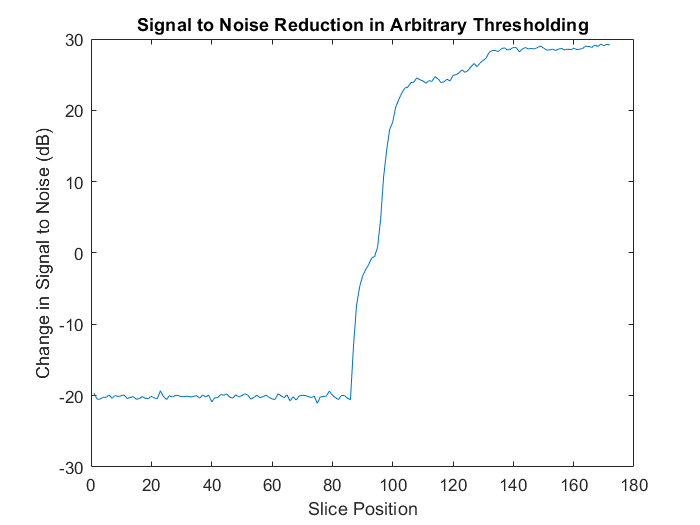

clf
plot(snrN - snrD)
ylabel('Change in Signal to Noise (dB)')
xlabel('Slice Position')
title('Signal to Noise Reduction in Arbitrary Thresholding')

Note: Large negative values mean that we are *introducing *noise into the matrix by performing too innacurate of a reconstruction. In other words, we are *losing *both signal and noise, with too much signal lost.

**For non-arbitrary square thresholding**

Original Signal to Noise Ratio at each slice along Z axis 

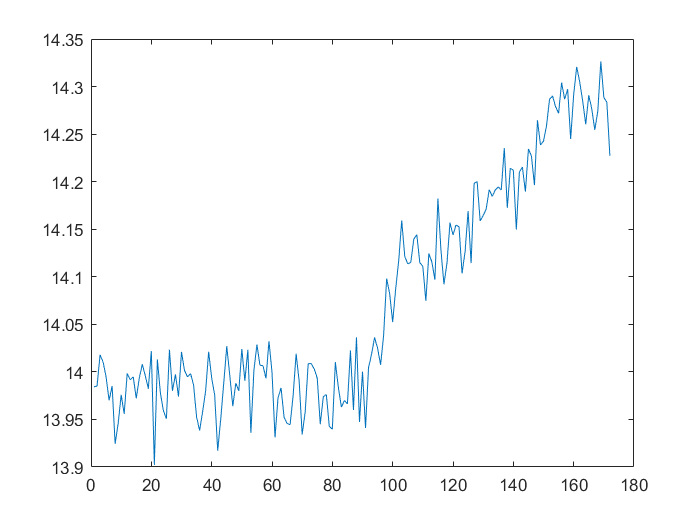

plot(snrNSq)

Denoised Signal to Noise Ratio at each slice along Z axis

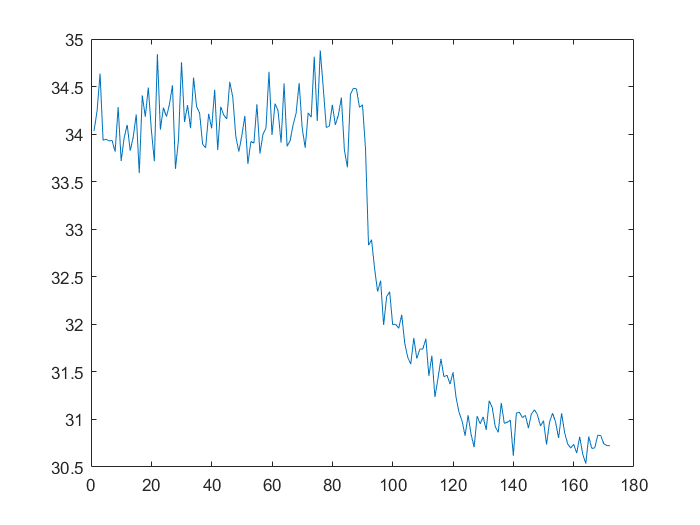

plot(snrDSq)

Amount of Signal to Noise Reduced by Non-arbitrary Optimal Hard Thresholding

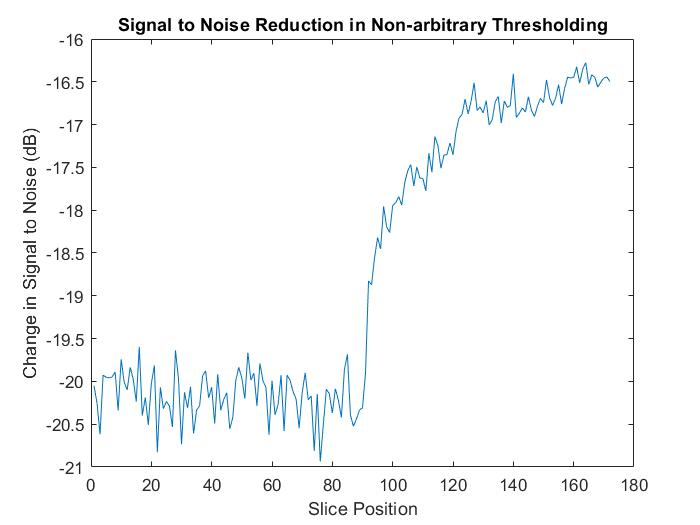

clf
plot(snrNSq - snrDSq)
ylabel('Change in Signal to Noise (dB)')
xlabel('Slice Position')
title('Signal to Noise Reduction in Non-arbitrary Thresholding')

**Example Brain Scan (Original, Noisey, Denoised)**

Arbitrary Thresholding

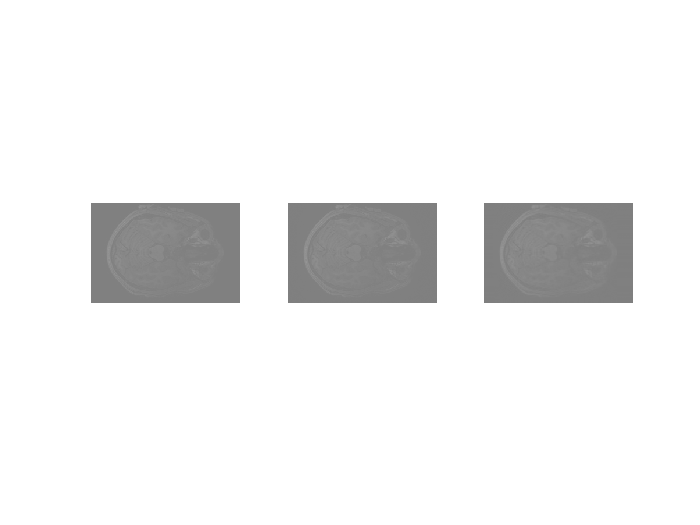

subplot(1,3,1)
imshow(Vol(:, :, 140));

subplot(1,3,2)
imshow(Nvol(:, :, 140));

subplot(1,3,3)
imshow(Dvol(:, :, 140))

Non-arbitrary thresholding

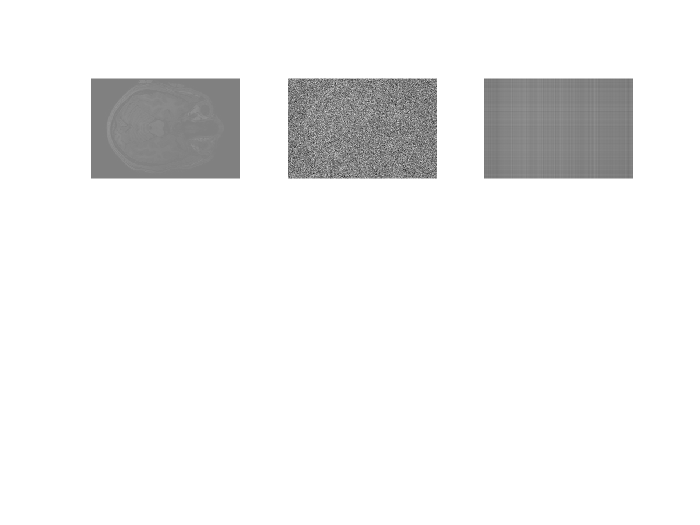

clf
subplot(2,3,1)
imshow(Vol(:, :, 140));

subplot(2,3,2)
imshow(NvolSq(:, :, 140));

subplot(2,3,3)
imshow(DvolSq(:, :, 140))

Average of SNR for Noisy and Denoised volumes

avgNoisy = mean(snrN)

avgNoisy = 74.0756

avgDenoised = mean(snrD)

avgDenoised = 72.7066

avgRank = mean(r)

avgRank = 20.6279